# Ground Truths Dataset 6



% combines ground_truths6p1, ground_truths6p2 and ground_truths6p3



## Clear workspace and all figures


clear all;clc;close all

%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);

%% Plot Range Profiles

fontsize1 = 12;
clims = [-40 0];

% Normalise data to have a peak of 0dB or 1 in linear scale
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
MaxRangeLine = (1/3.5)*MaxRangeLine

MaxRangeLine = 0.0750

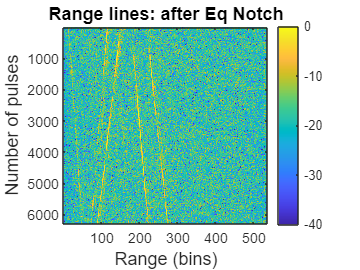

% Plot range lines
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Range lines: after Eq Notch','fontsize',fontsize1);

## Detection Point Calculations for Dataset 6

%final variable of detection points
Target_locations_DS6 = zeros(NumOfPulses, NumOfRangeBins);

% Parameters for sections of data to screenshot
stepSize = 100;
numIterations = ceil(NumOfPulses/stepSize)

numIterations = 63

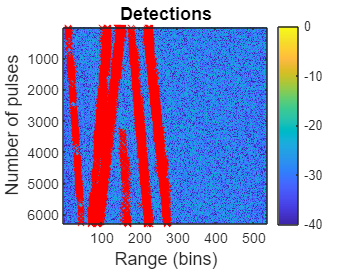

segment1end = 1035;
Iterations_segment1 = ceil(segment1end/stepSize);

load("Target_locations_DS6_p1.mat")
load("Target_locations_DS6_p2.mat")
load("Target_locations_DS6_p3.mat")
Target_locations_DS6 = Target_locations_DS6_p1 +Target_locations_DS6_p2 +Target_locations_DS6_p3;

% Manual removal of noise data points registered as targets 
for p = 188:200
    Target_locations_DS6(1:((p-187)*120+62), p) = 0;
end

for p = 201:229
    Target_locations_DS6(((p-200)*50):((p-200)*140+2000), p) = 0;
end

for p = 230:265
    Target_locations_DS6(((p-200)*50 + 2330):end, p) = 0;
end

for p = 230:244
    Target_locations_DS6(((p-229)*50 + 2330):end, p) = 0;
end

for p = 229:280
    Target_locations_DS6(1:((p-228)*100), p) = 0;
end

for p = 202:219
    Target_locations_DS6(((p-201)*85 + 4375):end, p) = 0;
end


Target_locations_DS6(:, 281:310) = 0;
Target_locations_DS6(1:381, 204:217) = 0;

% % Save the dataset to a .mat file
save('Target_locations_DS6.mat', 'Target_locations_DS6');

fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Target_locations_DS6 == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

function finalTargetPnts = detectionFinder(RangeProfiles,NumOfPulses,NumOfRangeBins, MaxRangeLine)
fontsize1 = 12;
    clims = [-40 0];
    % Normalise data to have a peak of 0dB or 1 in linear scale
    %[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles)));
    
    % Plot range lines
    figure; axes('fontsize',fontsize1);
    imagesc(20*log10(abs(RangeProfiles)./MaxRangeLine),clims);
    colormap('hot');
    colorbar;
    xlabel('Range (bins)','fontsize',fontsize1);
    ylabel('Number of pulses','fontsize',fontsize1);
    title('Range lines: after Eq Notch','fontsize',fontsize1);
    
    % Get the current figure handl
    fig = gcf;
    frame = getframe(fig);
    % Convert the captured frame to an RGB image:
    rgb_image = frame.cdata;
    % Convert RGB image to HSV color space:
    hsv_image = rgb2hsv(rgb_image);
    hsv_image = hsv_image(41:466, 82:556, :);
    
    
    hue_threshold = [0, 0.9]; % Adjust as needed
    saturation_threshold = [0, 0.8]; % Adjust as needed


    % Create binary mask based on hue and saturation thresholds:
    target_pnts = (hsv_image(:,:,1) >= hue_threshold(1) & hsv_image(:,:,1) <= hue_threshold(2)) & ...
              (hsv_image(:,:,2) >= saturation_threshold(1) & hsv_image(:,:,2) <= saturation_threshold(2));
    
    %imshow(target_pnts)

    target_pnts = double(target_pnts);
    [numtargetRows,numtargetCols] = size(target_pnts);
    
    target_pnts_resized = zeros(numtargetRows, NumOfRangeBins);
    for i = 1:numtargetRows
        targetsOriginalRowsize = 1:numel(target_pnts(i,:));
        targetsNewRowSize = linspace(1, numtargetCols, NumOfRangeBins);
        target_pnts_resized(i, :) = interp1(targetsOriginalRowsize, target_pnts(i,:), targetsNewRowSize, 'linear');
    end
    
    target_pnts_resized = abs(target_pnts_resized) ==1;
    target_pnts_resized = double(target_pnts_resized);
    finalTargetPnts = zeros(NumOfPulses, NumOfRangeBins); 
    
    for i = 1:NumOfRangeBins
        targetsOriginalColsize = 1:numel(target_pnts_resized(:,i));
        targetsNewRowSize = linspace(1, numtargetRows, NumOfPulses);
        finalTargetPnts(:, i) = interp1(targetsOriginalColsize, target_pnts_resized(:,i), targetsNewRowSize, 'linear');
    end
    
    finalTargetPnts = abs(finalTargetPnts) ==1;
    finalTargetPnts = double(finalTargetPnts);
end